%% =========================================================================
%  PI CONTROLLER PERFORMANCE ANALYSIS (PHYSICAL DATA) - MULTIPLE SETPOINTS
%  Each file corresponds to a different pressure setpoint
% =========================================================================

clear; clc; close all;

%% 1. CONFIGURATION

% ---- List of CSV files to analyze (each one at a different setpoint) ----
fileList = { ...
    'PI_32kpa.csv', ...
    'PI_36kpa.csv', ...
    'PI_37kpa.csv', ...
    'PI_42kpa.csv' ...
};

% ---- Corresponding pressure setpoints (kPa) for each file ----
refList_kPa = [ 32.0, 36.0, 37.0, 42.0 ];   % same order as fileList

% Desired design specs (for comparison)
ts_desired  = 1.0;   % Desired settling time (s)
Mp_desired  = 0.05;  % Desired overshoot (5% -> 0.05)

% Stepinfo configuration
SETTLING_THRESHOLD = 0.02;  % 2% settling band

% Threshold to detect when control becomes active
PWM_THRESHOLD = 5;

%% 2. PRE-ALLOCATE STORAGE

nFiles = numel(fileList);

t_cells  = cell(nFiles, 1);
p_cells  = cell(nFiles, 1);

results(nFiles) = struct( ...
    'fileName', '', ...
    'ref_kPa',  NaN, ...
    'P_base',   NaN, ...
    'P_final',  NaN, ...
    'ts',       NaN, ...
    'Mp',       NaN, ...
    'ess',      NaN ...
);

%% 3. MAIN LOOP OVER FILES

for k = 1:nFiles
    
    fileName = fileList{k};
    REF_KPA  = refList_kPa(k);
    
    fprintf('\n================ RUN %d: "%s" (Ref = %.2f kPa) ================\n', ...
        k, fileName, REF_KPA);
    
    results(k).fileName = fileName;
    results(k).ref_kPa  = REF_KPA;
    
    %% 3.1 LOAD DATA
    try
        data = readtable(fileName);   % assuming columns: t_ms, PWM, Presion_kPa
        t_ms  = data.t_ms;
        u_pwm = data.PWM;
        p_kPa = data.Presion_kPa;
        
        t_s = t_ms / 1000.0;          % convert to seconds
        
        fprintf('Data loaded successfully.\n');
    catch
        error('ERROR: Could not load file "%s". Check the file name and path.', fileName);
    end
    
    %% 3.2 DETECT CONTROL START
    
    idx_start_ctrl = find(u_pwm > PWM_THRESHOLD, 1, 'first');
    
    if isempty(idx_start_ctrl)
        % fallback: detect sudden change in pressure
        idx_change = find(abs(diff(p_kPa)) > 0.1, 1, 'first');
        if isempty(idx_change)
            error('ERROR: No active control detected in file "%s".', fileName);
        end
        idx_start_ctrl = idx_change;
    end
    
    % Start analysis a bit before the control starts
    idx_start_analysis = max(1, idx_start_ctrl - 100);  % ~100 samples before
    t_analysis = t_s(idx_start_analysis:end) - t_s(idx_start_analysis);
    p_analysis = p_kPa(idx_start_analysis:end);
    
    % Base pressure (before control activation)
    P_base = mean(p_kPa(idx_start_analysis : idx_start_ctrl - 1));
    results(k).P_base = P_base;
    
    fprintf('Base pressure (before control): %.3f kPa\n', P_base);
    
    %% 3.3 PERFORMANCE ANALYSIS (stepinfo with offset compensation)
    
    try
        info = stepinfo(p_analysis, t_analysis, REF_KPA, ...
                        'SettlingThreshold', SETTLING_THRESHOLD, ...
                        'InitialValue',      P_base);
        
        ts_real = info.SettlingTime;
        Mp_real = info.Overshoot;   % already in %
        
        % Final pressure: average of last 100 samples
        P_final = mean(p_analysis(max(1, end-100):end));
        ess_real = REF_KPA - P_final;  % steady-state error
        
    catch ME
        warning(['stepinfo failed for file "%s". Reason: %s\n' ...
                 'Using manual estimation for final pressure only.\n'], ...
                 fileName, ME.message);
        
        ts_real = NaN;
        Mp_real = NaN;
        P_final = mean(p_analysis(max(1, end-100):end));
        ess_real = REF_KPA - P_final;
    end
    
    results(k).P_final = P_final;
    results(k).ts      = ts_real;
    results(k).Mp      = Mp_real;
    results(k).ess     = ess_real;
    
    fprintf('\n--- PERFORMANCE RESULTS (RUN %d) ---\n', k);
    fprintf('Reference (P_ref):        %.3f kPa\n', REF_KPA);
    fprintf('Initial point (P_base):   %.3f kPa\n', P_base);
    fprintf('Final point   (P_final):  %.3f kPa\n', P_final);
    fprintf('Settling time (ts):       %.4f s\n', ts_real);
    fprintf('Overshoot     (Mp):       %.4f %%\n', Mp_real);
    fprintf('Steady-state error (ess): %.4e kPa\n', ess_real);
    
    % Store time/pressure segments for plotting
    t_cells{k} = t_analysis;
    p_cells{k} = p_analysis;
    
end


================ RUN 1: "PI_32kpa.csv" (Ref = 32.00 kPa) ================


Data loaded successfully.


Base pressure (before control): 5.230 kPa



--- PERFORMANCE RESULTS (RUN 1) ---


Reference (P_ref):        32.000 kPa


Initial point (P_base):   5.230 kPa


Final point   (P_final):  32.004 kPa


Settling time (ts):       3.0167 s


Overshoot     (Mp):       25.2531 %


Steady-state error (ess): -3.7228e-03 kPa



================ RUN 2: "PI_36kpa.csv" (Ref = 36.00 kPa) ================


Data loaded successfully.


Base pressure (before control): 7.003 kPa



--- PERFORMANCE RESULTS (RUN 2) ---


Reference (P_ref):        36.000 kPa


Initial point (P_base):   7.003 kPa


Final point   (P_final):  35.998 kPa


Settling time (ts):       3.0589 s


Overshoot     (Mp):       18.1250 %


Steady-state error (ess): 2.2079e-03 kPa



================ RUN 3: "PI_37kpa.csv" (Ref = 37.00 kPa) ================


Data loaded successfully.


Base pressure (before control): 8.394 kPa



--- PERFORMANCE RESULTS (RUN 3) ---


Reference (P_ref):        37.000 kPa


Initial point (P_base):   8.394 kPa


Final point   (P_final):  36.992 kPa


Settling time (ts):       3.0172 s


Overshoot     (Mp):       16.5216 %


Steady-state error (ess): 7.6238e-03 kPa



================ RUN 4: "PI_42kpa.csv" (Ref = 42.00 kPa) ================


Data loaded successfully.


Base pressure (before control): 6.146 kPa



--- PERFORMANCE RESULTS (RUN 4) ---


Reference (P_ref):        42.000 kPa


Initial point (P_base):   6.146 kPa


Final point   (P_final):  41.997 kPa


Settling time (ts):       3.7458 s


Overshoot     (Mp):       7.6929 %


Steady-state error (ess): 3.4851e-03 kPa



%% 4. GLOBAL PERFORMANCE SUMMARY (COMMAND WINDOW)

fprintf('\n=============================================================\n');

fprintf('SUMMARY OF KEY METRICS (ALL RUNS)\n');

SUMMARY OF KEY METRICS (ALL RUNS)


fprintf('-------------------------------------------------------------\n');

-------------------------------------------------------------


fprintf('Run | Ref (kPa) | Final P (kPa) |   ts (s)  |   Mp (%%)  |  ess (kPa)\n');

Run | Ref (kPa) | Final P (kPa) |   ts (s)  |   Mp (%)  |  ess (kPa)


fprintf('-------------------------------------------------------------\n');

-------------------------------------------------------------



for k = 1:nFiles
    fprintf('%3d | %8.3f | %13.3f | %8.4f | %8.4f | %10.4f\n', ...
        k, ...
        results(k).ref_kPa, ...
        results(k).P_final, ...
        results(k).ts, ...
        results(k).Mp, ...
        results(k).ess);
end

  1 |   32.000 |        32.004 |   3.0167 |  25.2531 |    -0.0037
  2 |   36.000 |        35.998 |   3.0589 |  18.1250 |     0.0022
  3 |   37.000 |        36.992 |   3.0172 |  16.5216 |     0.0076
  4 |   42.000 |        41.997 |   3.7458 |   7.6929 |     0.0035



fprintf('-------------------------------------------------------------\n');

-------------------------------------------------------------


fprintf('Desired specs: ts <= %.2f s, Mp <= %.2f %%\n', ...
        ts_desired, Mp_desired*100);

Desired specs: ts <= 1.00 s, Mp <= 5.00 %


fprintf('=============================================================\n\n');

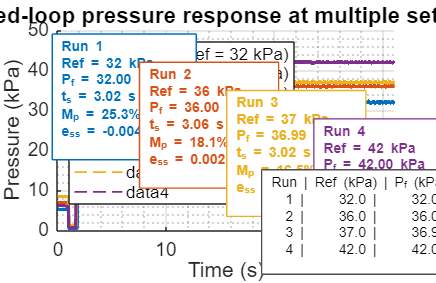


%% 5. VISUALIZATION (PRESSURE ONLY, ALL RUNS, WITH MOVABLE INFO BOXES)

figure('Name', 'PI Controller Performance - Multiple Setpoints', ...
       'Color', 'w', ...
       'Position', [100, 100, 1000, 650]);

ax = axes; %#ok<NASGU>
hold on; grid on; grid minor;
set(gca, 'FontSize', 12);

colors = lines(nFiles);   % distinct colors for each run

% Plot responses
for k = 1:nFiles
    plot(t_cells{k}, p_cells{k}, ...
         'LineWidth', 2, ...
         'Color', colors(k,:), ...
         'DisplayName', sprintf('Run %d (Ref = %.0f kPa)', ...
                                k, results(k).ref_kPa));
end

% Plot reference lines (for visual comparison)
t_max_global = max(cellfun(@(v) v(end), t_cells));

for k = 1:nFiles
    REF_KPA = results(k).ref_kPa;
    plot([0 t_max_global], REF_KPA*[1 1], ...
         '--', 'Color', colors(k,:), ...
         'LineWidth', 1);
end

xlabel('Time (s)');
ylabel('Pressure (kPa)');
title('Closed-loop pressure response at multiple setpoints', 'FontSize', 14);
legend('Location', 'northwest');

%% 5.1 POSITIONS FOR INFO BOXES (YOU CAN TUNE THESE)

% Positions in normalized figure units [x y width height]
labelPos = [ ...
    0.12 0.70 0.16 0.18;  % Run 1
    0.32 0.60 0.16 0.18;  % Run 2
    0.52 0.50 0.16 0.18;  % Run 3
    0.72 0.40 0.16 0.18]; % Run 4

%% 5.2 CREATE ANNOTATION TEXTBOXES (DRAGGABLE, WITH e_ss HUMAN-READABLE)

for k = 1:nFiles
    
    labelStr = sprintf(['Run %d\nRef = %.0f kPa\nP_f = %.2f kPa\n' ...
                        't_s = %.2f s\nM_p = %.1f%%\n' ...
                        'e_{ss} = %.3f kPa'], ...
        k, ...
        results(k).ref_kPa, ...
        results(k).P_final, ...
        results(k).ts, ...
        results(k).Mp, ...
        results(k).ess);
    
    annotation('textbox', labelPos(k,:), ...
        'String', labelStr, ...
        'FitBoxToText', 'on', ...
        'BackgroundColor', 'w', ...
        'EdgeColor', colors(k,:), ...
        'Color', colors(k,:), ...
        'FontSize', 9, ...
        'FontWeight', 'bold', ...
        'Interpreter', 'tex');  % para que e_{ss} se vea bonito
end

%% 5.3 GLOBAL METRICS TABLE AS A TEXTBOX (POSTER FRIENDLY)

metricsCell = cell(nFiles+1, 1);
metricsCell{1} = sprintf('Run | Ref (kPa) | P_f (kPa) | t_s (s) | M_p (%%) | e_{ss} (kPa)');

for k = 1:nFiles
    metricsCell{k+1} = sprintf('%3d | %8.1f | %9.2f | %7.3f | %7.2f | %10.3f', ...
        k, ...
        results(k).ref_kPa, ...
        results(k).P_final, ...
        results(k).ts, ...
        results(k).Mp, ...
        results(k).ess);
end

annotation('textbox', [0.60 0.10 0.38 0.30], ...  % [x y w h]
    'String', metricsCell, ...
    'FitBoxToText', 'on', ...
    'BackgroundColor', [1 1 1], ...
    'EdgeColor', [0.3 0.3 0.3], ...
    'FontSize', 9, ...
    'Interpreter', 'tex');


%% 6. SPEC CHECK (MEETS / DOES NOT MEET)

fprintf('SPECIFICATION CHECK PER RUN:\n');

SPECIFICATION CHECK PER RUN:


for k = 1:nFiles
    ts_ok  = ~isnan(results(k).ts) && (results(k).ts <= ts_desired);
    Mp_ok  = ~isnan(results(k).Mp) && (results(k).Mp <= Mp_desired*100);
    ess_ok = abs(results(k).ess) < 0.1;   % 0.1 kPa tolerance
    
    fprintf('\nRun %d (%s, Ref = %.2f kPa):\n', ...
        k, results(k).fileName, results(k).ref_kPa);
    fprintf('  Settling time: ts = %.4f s -> %s\n', ...
        results(k).ts, logical_to_status(ts_ok));
    fprintf('  Overshoot:     Mp = %.4f %% -> %s\n', ...
        results(k).Mp, logical_to_status(Mp_ok));
    fprintf('  Steady-state error: ess = %.4f kPa -> %s\n', ...
        results(k).ess, logical_to_status(ess_ok));
end


Run 1 (PI_32kpa.csv, Ref = 32.00 kPa):


  Settling time: ts = 3.0167 s -> DOES NOT MEET


  Overshoot:     Mp = 25.2531 % -> DOES NOT MEET


  Steady-state error: ess = -0.0037 kPa -> MEETS



Run 2 (PI_36kpa.csv, Ref = 36.00 kPa):


  Settling time: ts = 3.0589 s -> DOES NOT MEET


  Overshoot:     Mp = 18.1250 % -> DOES NOT MEET


  Steady-state error: ess = 0.0022 kPa -> MEETS



Run 3 (PI_37kpa.csv, Ref = 37.00 kPa):


  Settling time: ts = 3.0172 s -> DOES NOT MEET


  Overshoot:     Mp = 16.5216 % -> DOES NOT MEET


  Steady-state error: ess = 0.0076 kPa -> MEETS



Run 4 (PI_42kpa.csv, Ref = 42.00 kPa):


  Settling time: ts = 3.7458 s -> DOES NOT MEET


  Overshoot:     Mp = 7.6929 % -> DOES NOT MEET


  Steady-state error: ess = 0.0035 kPa -> MEETS


fprintf('\nDone.\n');


Done.



%% LOCAL FUNCTION: BOOLEAN -> STRING
function status = logical_to_status(cond)
    if cond
        status = 'MEETS';
    else
        status = 'DOES NOT MEET';
    end
end
